# Measuring Boltzmann's constant using video microscopy

This matlab live script will analyze brownian motion to determine boltzmann constant.  

This script mirrors the awesome IDL tutorial posted by Eric Weeks: 

[https://physics.emory.edu/faculty/weeks/idl/tracking.html](https://physics.emory.edu/faculty/weeks/idl/tracking.html)

Matlab functions are not identical to the IDL functions -- some 'keywords' were ignored -- but they are very similar.  

## Part #1: Reading in video file - reaf.vif.m

In our research lab, we use XCAP software by EPIX to grab video files (VIF). These can be converted into images using XCAP, but the Matlab function 'read_vif.m' can also read these VIF files, although it often needs to be tweaked. Read the header of read_vif for more information.  

clear all
cd('C:\Users\75KAPTOWICZ\OneDrive - West Chester University of PA\Documents\0 WCU - Misc\Matlab\Kevin_Particle_Tracking\Drafts')
filename = "NIST 1.vif"; pix_w=658; pix_h=494;
max255='y';

%frame=200;
%a = read_vif(filename,pix_w,pix_h,bit_10_unpacked='y',byte_offset=72,frame_N=frame);

a = read_vif(filename,pix_w,pix_h,bit_10_unpacked='y',byte_offset=72);

Setting byte_spacing to pad frames to interger*512 bytes.
...... byte_spacing = 136 bytes


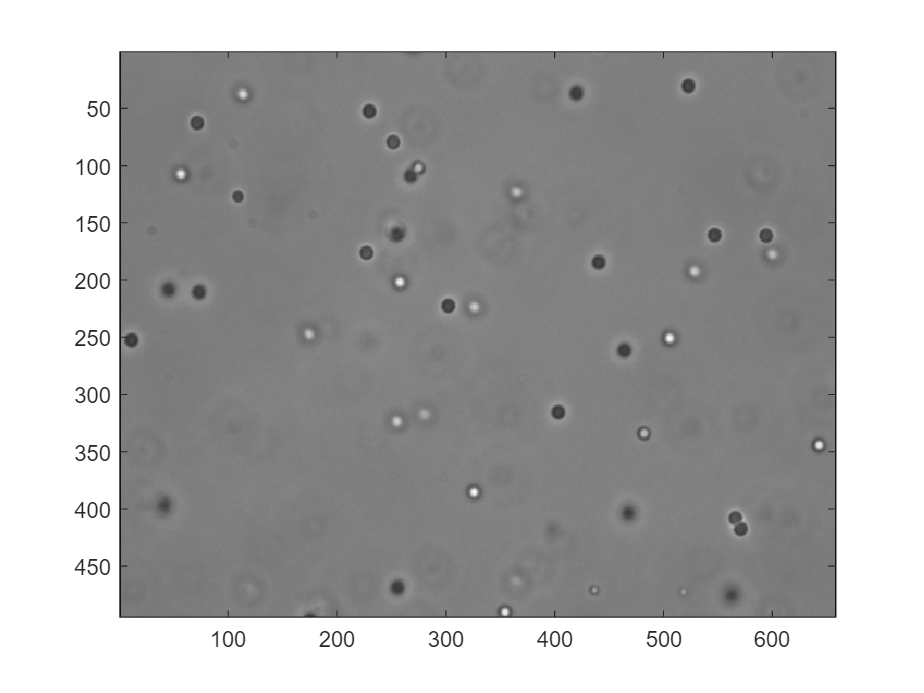


% Image of first frame in array
frame=1;
colormap('gray'); imagesc(a(:,:,frame));

## Part #2: Preprocessing of images - bpass.m

The function** bpass** is a spatial bandpass filter which smooths the image and subtracts the background off.  The two numbers are the spatial wavelength cutoffs in pixels.  The first one is almost always '1'. The second number should be something like the diameter of the 'blob's you want to find in pixels.  Try a few values and use the one that gives you nice, sharply peaked circular blobs where your particles were; remember the numbers you used for **bpass**. 

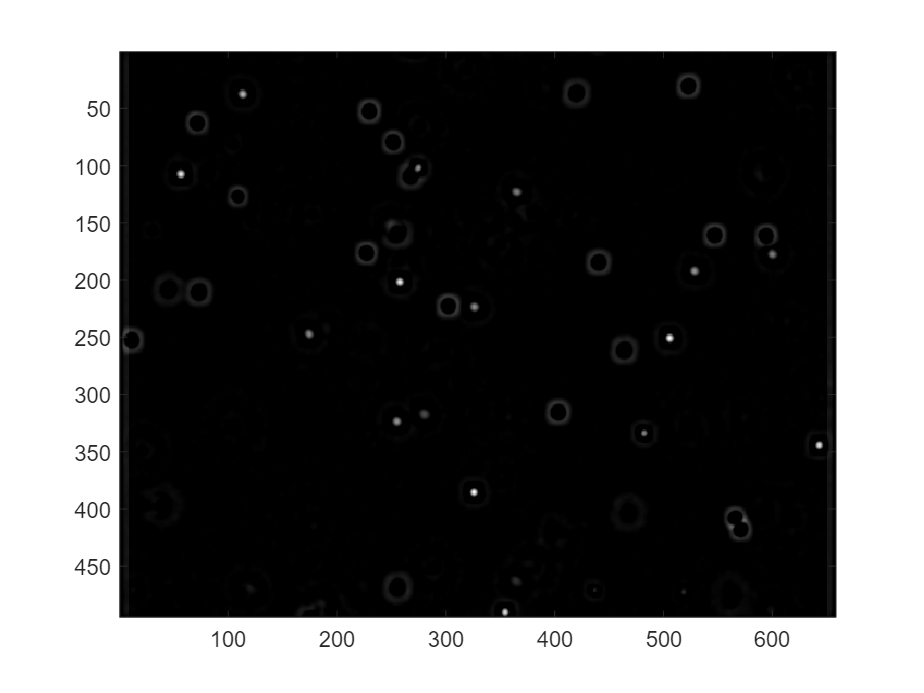

a0 = a(:,:,frame);
lnoise=1; lobject=7;
b = bpass(a0,lnoise,lobject);
colormap('gray'); image(b);

## Part #3: Tuning tracking parameter - findfeaures.m

findfeatures.m acts the same way as 'feature' does in IDL (I couldn't call it the same name because of built in functions).  The each row represents a found feature.  The columns in each row are: (1) x-position, (2) y-position, (3) total brighness, (4) radius of gyration, and (5) eccentricity. 

f = findfeatures(b,11,min=90,quiet=[]);

FINDFEATURES: 17 features found.


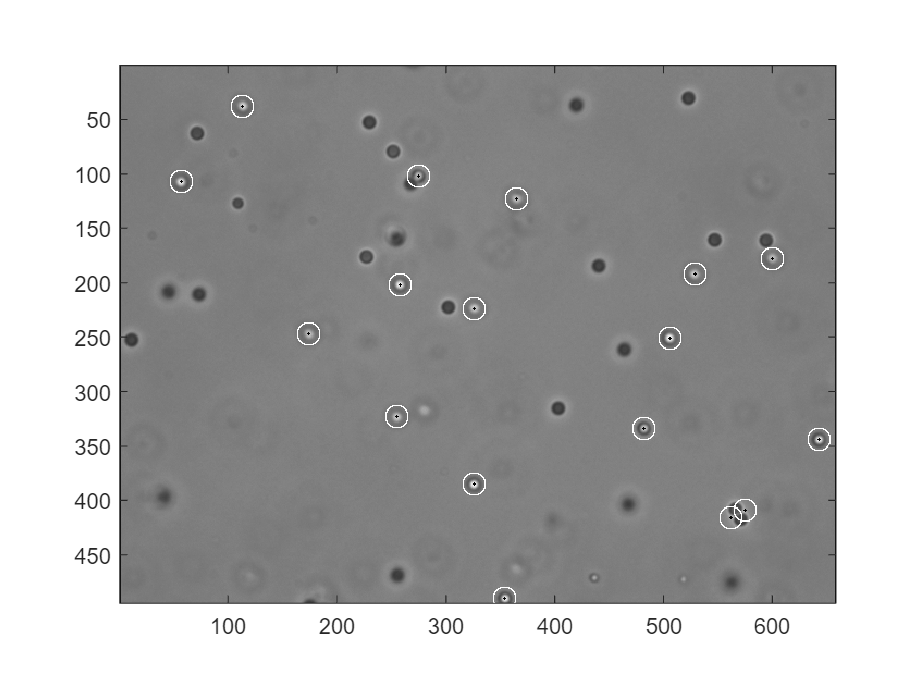

fo=fover2d(a0,f,circle=1, radius=11);

## Step #4: Create pretrack - epretrack.m

pt_all=epretrack(a,bplo=1,bphi=9,dia=11,min=100);

Defaults: sep-unset mass-unset
starting epretrack...
FINDFEATURES: 17 features found.
FINDFEATURES: 15 features found.
FINDFEATURES: 15 features found.
FINDFEATURES: 14 features found.
FINDFEATURES: 15 features found.
FINDFEATURES: 14 features found.
FINDFEATURES: 13 features found.
FINDFEATURES: 15 features found.
FINDFEATURES: 16 features found.
FINDFEATURES: 14 features found.
FINDFEATURES: 14 features found.
FINDFEATURES: 14 features found.
FINDFEATURES: 12 features found.
FINDFEATURES: 12 features found.
FINDFEATURES: 11 features found.
FINDFEATURES: 11 features found.
FINDFEATURES: 14 features found.
FINDFEATURES: 12 features found.
FINDFEATURES: 13 features found.
FINDFEATURES: 12 features found.
FINDFEATURES: 12 features found.
FINDFEATURES: 14 features found.
FINDFEATURES: 13 features found.
FINDFEATURES: 12 features found.
FINDFEATURES: 13 features found.
FINDFEATURES: 12 features found.
FINDFEATURES: 13 features found.
FINDFEATURES: 11 features found.
FINDFEATURES: 11 featur

pt=pt_all;

plot(pt(:,1),pt(:,2),'.')
drawnow

% Cleanup 
w=find(pt(:,5) < 0.08); % Find particles with eccentricity less than 0.08
pt=pt(w,:);

## Step #5: Analyze pretrack file

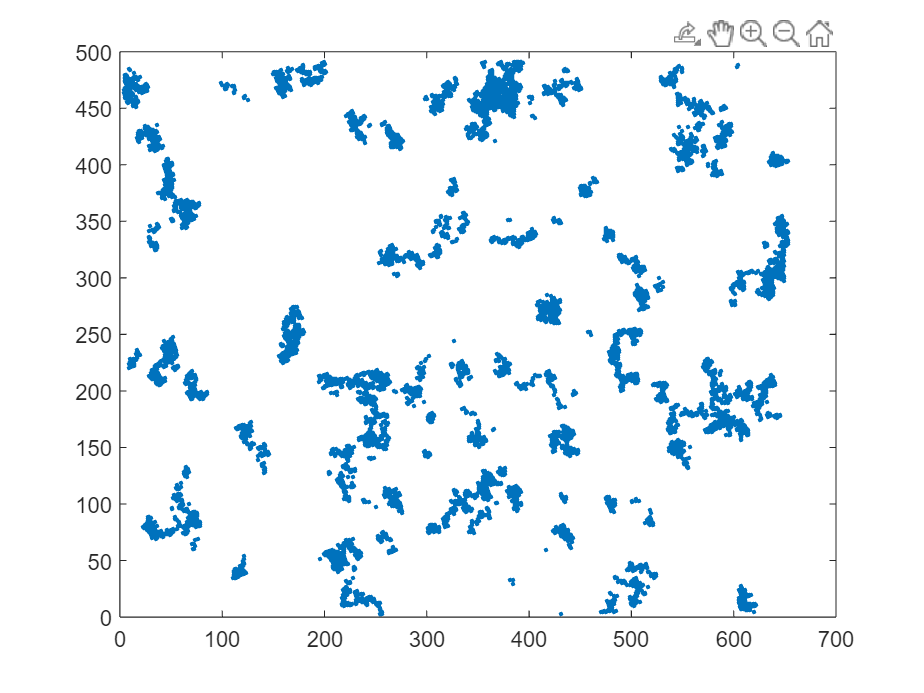

%fo=fover2d(a,pt,circle='y',radius=11,big='y');

plot(pt(:,1),pt(:,2),'.')

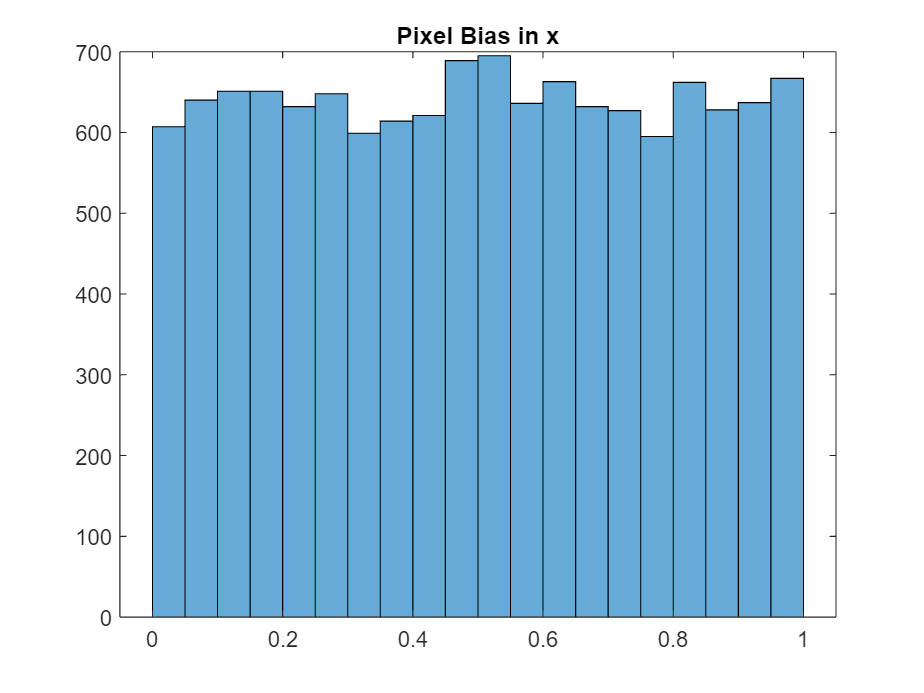


% Check Pixel Biasing
histogram(mod(pt(:,1),1),20);
title('Pixel Bias in x')

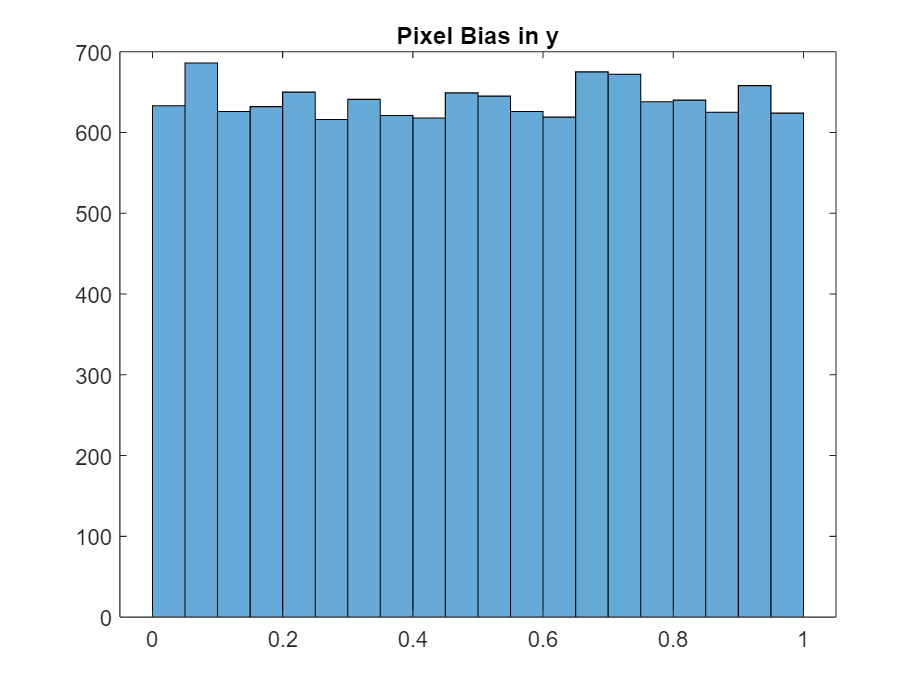

histogram(mod(pt(:,2),1),20);
title('Pixel Bias in y')

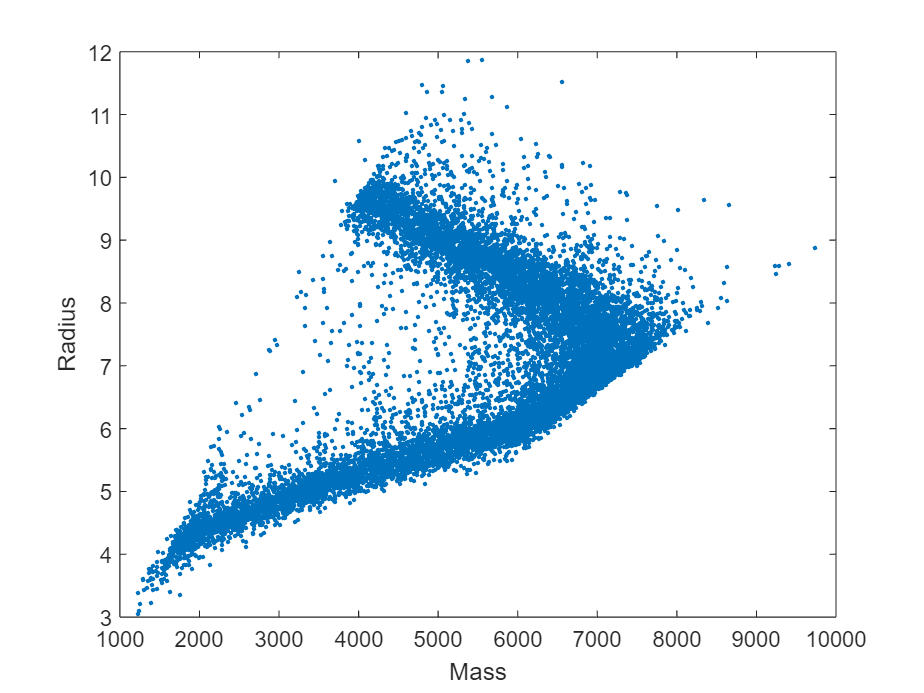



plot(pt(:,3),pt(:,4),'.')
xlabel('Mass')
ylabel('Radius')


plot(pt(:,3),pt(:,5),'.')
xlabel('Mass')
ylabel('Eccentricity')

% Movie of subset of particles
w=find(pt(:,3) < 2500); % Movie of particles with low mass
if ~isempty(w)
fo=fover2d(a,pt(w,:),circle='y',radius=11,big='y');
end

## Step #4: Create tracks

% NEXT UP
t=track(pt,6,dim=2,memory=5,goodenough=1);
%plottr(t,ID=1)
%plottr(t,goodenough=50)

## Step #5: Calculate MSD

m=msd(t,quiet='y',minN=100);
loglog(m(:,1),m(:,6),'-o')

## Step #6: Get Slope

x=m(:,1);
y=m(:,6);

N=length(x) % Number of datapoints
Delta = N*(sum(x.^2))-(sum(x).^2);  % Determine Delta
A = ((sum(x.^2))*(sum(y))-(sum(x))*sum(x.*y))/Delta % Calculate Constant A
B = (N*sum(x.*y)-(sum(x))*(sum(y)))/Delta % Calculate Constant B

sigma_y = sqrt((1/(N-2))*sum((y-A-B*x).^2)) % Calculate sigma y
sigma_A = sigma_y*sqrt(sum(x.^2)/Delta) % Calculate sigma A
sigma_B = sigma_y*sqrt(N/Delta) % Calculate sigma B

Graph Fit

% Display results
%hold off
plot(x,y,'ko','MarkerFaceColor', 'k')
drawnow
hold on
plot(x,A+B*x,'-k')
hold off
drawnow
xlabel('{\it x} value') %\it to make x italics
ylabel('{\it y} value')
title('Linear fit to sample data')
disp('Calculating the linear fit parameters:')
disp(['The intercept from fit is ', num2str(round(A,1),2),' +/- ', num2str(round(sigma_A,1),2)])
disp(['The slope is ', num2str(round(B,2),4),' +/- ', num2str(round(sigma_B,1),2)])

data=mkpdf(t,1); 
histfit(data(:),100,'normal'); 
set(gca,'YScale','log')
drawnow

data=mkpdf(t,10); 
histfit(data(:),100,'normal'); 
set(gca,'YScale','log')
drawnow
